Question 1a

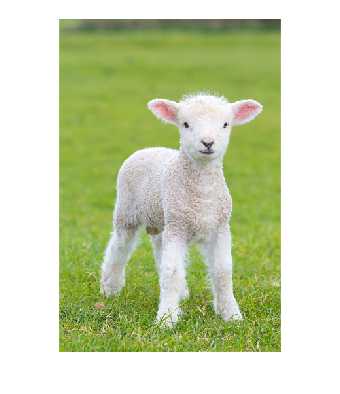

img1_location = './Assignment 1/lamb.jpg';
img2_location = './Assignment 1/Goku.png';
% Read the image into the workspace
img1 = imread(img1_location);
img2 = imread(img2_location);
% Show the image
figure('Name','A lamb');
imshow(img1);

imwrite(img1, './Assignment 1/Q1-a.png');

Question 1b

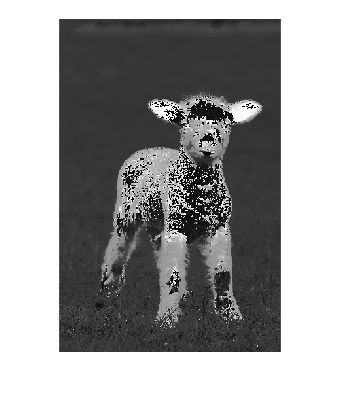

% Convert the image into HSV color space
hsv_converted_img = rgb2hsv(img1);
% Assign each channel to a variable
h = hsv_converted_img(:,:,1);
s = hsv_converted_img(:,:,2);
v = hsv_converted_img(:,:,3);
% Display each channel separately
figure('Name','H channel'), imshow(h);

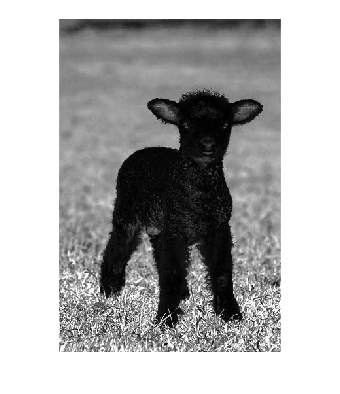

figure('Name','S channel'), imshow(s);

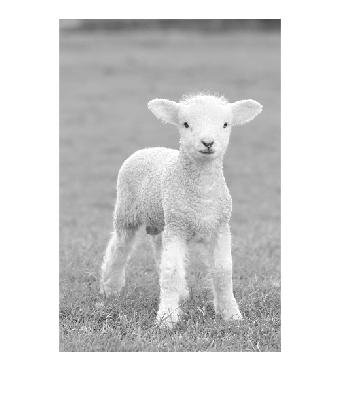

figure('Name','V channel'), imshow(v);

imwrite(h, './Assignment 1/Q1-H_channel.png');
imwrite(s, './Assignment 1/Q1-S_channel.png');
imwrite(v, './Assignment 1/Q1-V_channel.png');

Question 1c

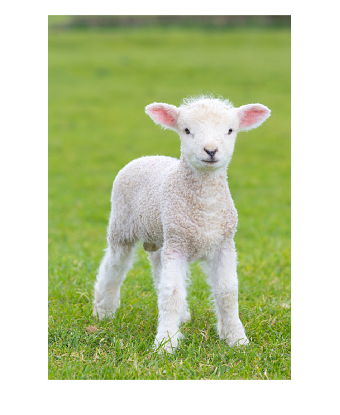

% Enlarge the image by twice
enlarged_img1 = imresize(img1, 2);
[x y] = size(img1);
figure('Name','Enlarged image'), imshow(enlarged_img1);

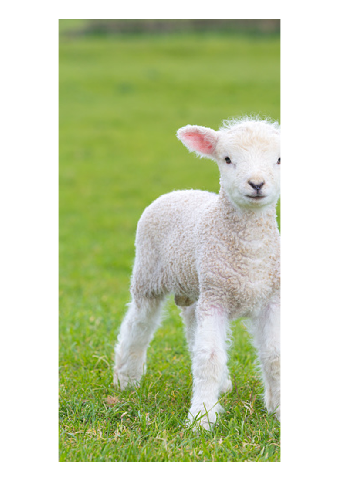

% crop the enlarged image to its original size
cropped_img1 = imcrop(enlarged_img1, [0 0 x y]);
figure('Name','Cropped image'), imshow(cropped_img1);

imwrite(enlarged_img1, './Assignment 1/Q1-enlarged_img.png');
imwrite(cropped_img1, './Assignment 1/Q1-cropped_img.png');

Question 1d

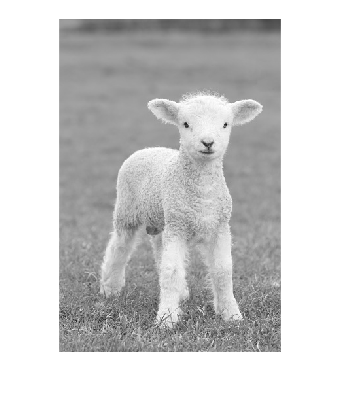

% Convert the color image into gray scale
gray_img1 = rgb2gray(img1);
imshow(gray_img1);

imwrite(gray_img1, './Assignment 1/Q1-Gray_img.png');

Question 1e

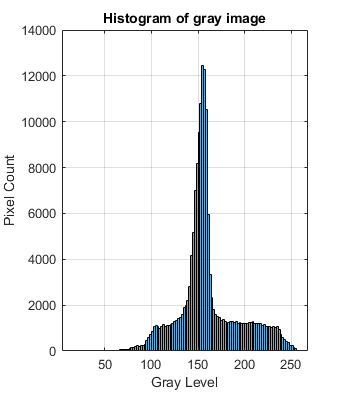

% Generate the histogram of the grayscale image and display it to screen (10 points)
h = histogram(gray_img1);
grid on;
title('Histogram of gray image');
xlabel('Gray Level');
ylabel('Pixel Count');
saveas(h, './Assignment 1/Q1-Histogram', 'png');

Question 2

% Question 2
convert_table = hist_matching(img1, img2);

table_1 =      0     0
     1     0
     2     0
     3     0
     4     5
     5     6
     6     7
     7     7


result = 8×2 table
    r input    z output
    _______    ________

       0          2    
       1          2    
       2          2    
       3          2    
       4          7    
       5          7    
       6          7    
       7          7    


function result = mapping_table(image, bit)
% A function that turns an input histogram equalization lookup table to an output one
    % A function that turns a grayscale image to transformation lookup table
    function result = hist_table(image, bit)
        bins = 2^bit;
        gray_values = (0:bins-1).';
        r = gray_values ./ (bins-1);
        % Return pixel probabbilities and their ranges
        [prob,ranges] = histcounts(image, bins, 'Normalization', 'probability');
        prob = prob.';
        result = [gray_values r prob cumsum(prob) .* bins-1]; 
    end

    table = hist_table(image, bit);
    bins = 2^bit;
    result = ones(8,2) * (bins - 1); % Initializa a table
%     table = table{:,:}; % Convert to matrix
    k = table(:,1); % Extract the first column
    result(:,1) = k;
    s_k = table(:,2); % Extract the second column
    c = table(:,4);
%     Compare value of c and assign it to the proper probabbility
    for ii = 1:height(table)
        for jj = 1:height(table)-1
            if c(ii) <= round(k(jj))
                result(ii,2) = k(jj);
                break
            end
        end
    end

end

% A function to achieve histogram matching
function result = hist_matching(iMat1, iMat2, bit)
% Make sure the input images are grayscaled
    if size(iMat1,2) > 1
        iMat1 = rgb2gray(iMat1);
    end
    if size(iMat2,2) > 1
        iMat2 = rgb2gray(iMat2);
    end
    table_1 = mapping_table(iMat1,3)
    result = table_1;
    table_2 = mapping_table(iMat2,3);
    % Col1,2: r->s, col3,4: s->z
    lookup = [table_1 table_2];
    for index = 1:height(lookup)
        input = lookup(index,2);
        % Find the first index of value "input" in the third column
        id = find(lookup(:,3) == input, 1);
        target = lookup(id,4);
%         fprintf('%d -> %d, %d -> %d\n', lookup(index,1), input, ...
%             lookup(id, 3), target);
        result(index, 1:2) = [lookup(index,1) target];
    end
    result = array2table(result, 'VariableNames', {'r input', 'z output'})
end